# Turbine Calcs

% Geometry
d_i = 1.835/39.37; % m
d_a = 2.52/39.37; % m
d_m = (d_i + d_a)/2; % m
beta1 = 30; % [degrees] (assumed beta1 = beta2)

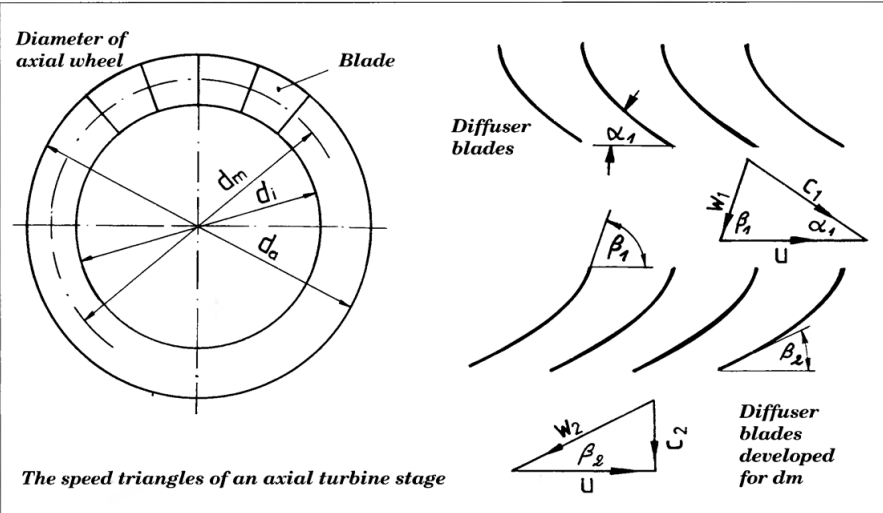

% Properties

u_max = 300; % max peripheral speed [m/s]
n_max = u_max/(d_a * pi); % max rotational speed [1/s]
u = d_m * pi * n_max; % mean peripheral speed [m/s]
c2 = u * tand(beta); % outlet speed [m/s]

gas_T = 873; % max gas temp [K]
rho_N = 1.225; % avg density of air [kg/m^3]
rho = rho_N * (273/gas_T); % density of air given temp [kg/m^3]
outlet_A = (d_a^2 - d_i^2)*pi/2; % Outlet Area [m^2]
m_dot = outlet_A * c2 * rho; % mass flow rate out of outlet (assumed just air) [kg/s]
F = m_dot * c2; % estimated thrust [N]

Cp = 1000; % specific heat of air costant pressure [J/kg*K]
T1 = 293; % temperature before inlet [K]
compression_ratio = (((.6*u^2)/(Cp*T1))+1)^(1/0.285); % compression ratio of compressor
P_W = (m_dot*u^2)/1000; % Shaft power [KWatt]

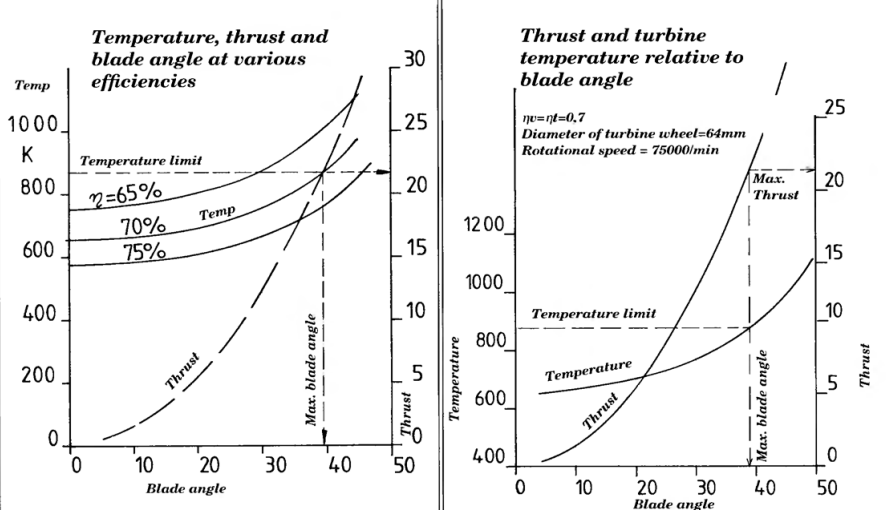

% Thermo analysis 
delta_T = 743 - T1; % [K]
delta_d = .000016 * delta_T * d_a *1000;